# Prepare differentially expressed gene profiles from CCLE RNASeq dataset

## Summary

## Load Data

### Load metabolic reconstruction

load ~/Data/Reconstructions/eGEM/07132020.mat; % Latest version of eGEM model
entrez = string(eGEM.geneEntrezID);

### Load RNASeq data

filename = '~/Data/RNASeq/CCLE/Mapped_Processed_CCLE_effect.csv';
effect = readmatrix(filename);

filename = '~/Data/RNASeq/CCLE/Mapped_Processed_CCLE_pvalue.csv';
pvalue = readmatrix(filename);

### Get intersection between metabolic model and RNASeq data

[~, ia, ib] = intersect(entrez, string(effect(:, 2)));
effect = effect(ib, :);
pvalue = pvalue(ib, :);

Read in the column names of the csv files.

filename = '~/Data/RNASeq/CCLE/colnames.csv';
fid = fopen(filename, 'rt');
colnames = textscan(fid, '%s', 'Delimiter',',');
fclose(fid);
colnames = colnames{1};

colnames = 979×1 cell array
    {'ENSEMBL'        }
    {'ENTREZID'       }
    {'SYMBOL'         }
    {'CHP126'         }
    {'CHP212'         }
    {'IMR32'          }
    {'KELLY'          }
    {'KPNRTBM1'       }
    {'KPNSI9S'        }
    {'KPNYN'          }
    {'MHHNB11'        }
    {'NB1'            }
    {'NH6'            }
    {'SIMA'           }
    {'SKNAS'          }
    {'SKNBE2'         }
    {'SKNDZ'          }
    {'SKNFI'          }
    {'SKNSH'          }
    {'A673'           }
    {'CADOES1'        }
    {'CAL78'          }
    {'EW8'            }
    {'EWS502'         }
    {'G292CLONEA141B1'}
    {'HOS'            }
    {'HS706T'         }
    {'MG63'           }
    {'MHHES1'         }
    {'RDES'           }


Reformat the data.

entrez_ids = pvalue(:, 2);

entrez_ids =          100
       10005
       10007
       10020
       10026
       10050
       10057
       10087
       10090
       10157


effect(:, 1:3) = [];
pvalue(:, 1:3) = [];
colnames(1:3) = [];

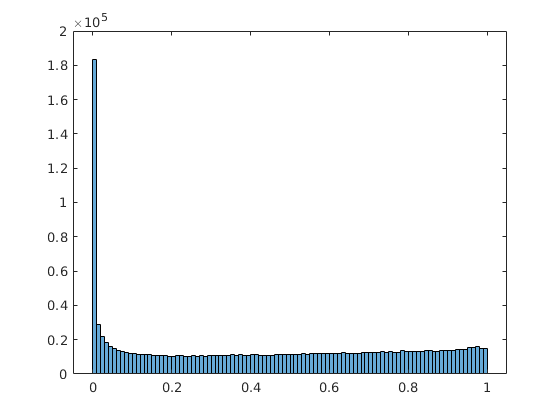

histogram(pvalue, 100)

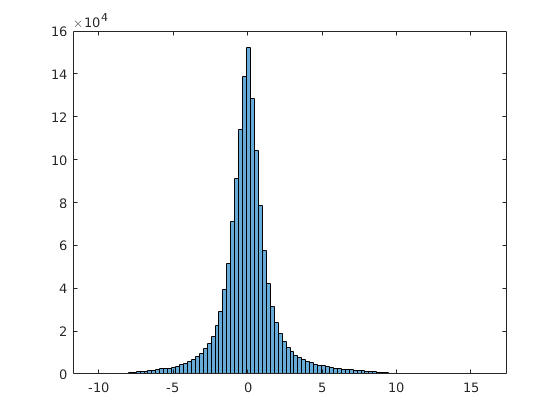

histogram(effect, 100)